close all; clear; clc;

(1) use explicit (and simple) form of U to prove function is functional

a = ones(3,1)/sqrt(3);
A = eye(3);
p = pi/2;
s = 0;

[az, el, r] = cart2sph(a(1), a(2), a(3));

for 0 1 0 0 0 ( => 0.5732i )

l1 = 1;
m1 = 0;
l = 0;
m = 0;

IUR_SE3(a, A, p, s, l1, l, m1, m) 

ans = 0.0000 + 0.5732i

1i*sqrt(3)*cos(el)*(-cos(r*p)+sin(r*p)/(r*p))/(r*p)

ans = 0.0000 + 0.5732i

for 0 2 1 0 0  ( => 0.1255 - 0.1255i )

l1 = 2;
m1 = 1;
l = 0;
m = 0;

IUR_SE3(a, A, p, s, l1, l, m1, m) 

ans = 0.1255 - 0.1255i

-1/r^3/p^3 * sqrt(15/8) * exp(-1i*az) ...
    * (3*r*p*cos(r*p) -3*sin(r*p) ...
    +r^2*p^2*sin(r*p)) * sin(2*el)

ans = 0.1254 - 0.1254i

(2) prove $U_1(g_1,p,s)U_2(g_2,p,s)=U(g_1 \circ g_2, p,s)$

randomly generate $A_1$and $a_1$, $A_2$ and $a_2$

a1 = rand(3,1)

a1 =     0.0844
    0.3998
    0.2599


A1 = gen_SO3

A1 =    -0.4503    0.8402    0.3023
   -0.3368    0.1537   -0.9289
   -0.8269   -0.5201    0.2138


a2 = rand(3,1)

a2 =     0.1818
    0.2638
    0.1455


A2 = gen_SO3

A2 =     0.8901    0.3730    0.2620
    0.2918   -0.9078    0.3012
    0.3502   -0.1917   -0.9169


calculate $(g_1 \circ g_2) (A_1 A_2, A_1 a_2 + a_1)$

aa = A1*a2+a1;
AA = A1*A2;

p = pi/2;
s = 2;
l1 = 5;
l = 5;

calculate $U_1(g_1, p, s)$, $U_2(g_2, p, s)$ respectively:

U1 = IUR_SE3(a1, A1, p, s, l1, l);
U2 = IUR_SE3(a2, A2, p, s, l1, l);

calculate $U_1(g_1,p,s)U_2(g_2,p,s)$

U_multi = U1*U2;

calculate $U(g_1 \circ g_2, p, s)$

UU = IUR_SE3(aa, AA, p, s, l1, l);

compare $U_1 U_2$ and $U(g_1 \circ g_2)$ using *imagesc *function:

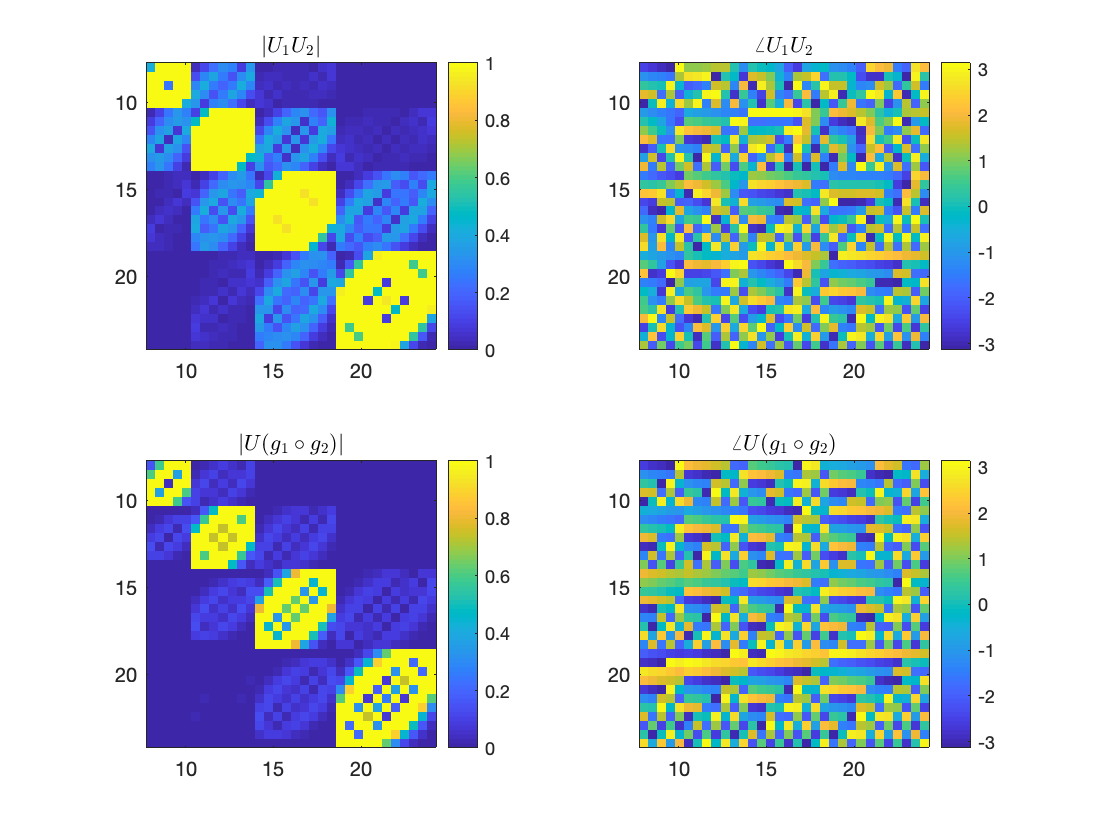

L = max(l1(end), l(end));
size = (L+1)^2-s^2;
h = figure; set(h, 'defaulttextinterpreter', 'latex');
mid_part = floor(size/4):1:ceil(size*3/4);
clims = [0 1];  % ignore terms with extreme values
subplot(2,2,1); imagesc(mid_part, mid_part, abs(U_multi), clims); colorbar; title('$|U_1 U_2|$');
subplot(2,2,2); imagesc(mid_part, mid_part, angle(U_multi)); colorbar; title('$\angle U_1 U_2$')
subplot(2,2,3); imagesc(mid_part, mid_part, abs(UU), clims); colorbar; title('$|U(g_1 \circ g_2)|$');
subplot(2,2,4); imagesc(mid_part, mid_part, angle(UU)); colorbar; title('$\angle U(g_1 \circ g_2)$');

(3) prove $U = \exp(u)$

randomly generate $A
$ and $a$:

a = rand(3,1)

a =     0.5499
    0.1450
    0.8530


A = gen_SO3

A =     0.2662   -0.7185   -0.6426
    0.3720    0.6915   -0.6192
    0.8893   -0.0742    0.4513


p = pi/2;
s = 3;
l1 = 6;
l = 6;

U = IUR_SE3(a, A, p, s, l1, l);

G = [A, a; zeros(1,3), 1];  % G \in SE(3)
g = logm(G);                % g \in se(3)

u = diff_iur_se3(g, p, s, l1, l);

U_exp = expm(u);

compare $U$ and $exp(u)$ using *imagesc *function:

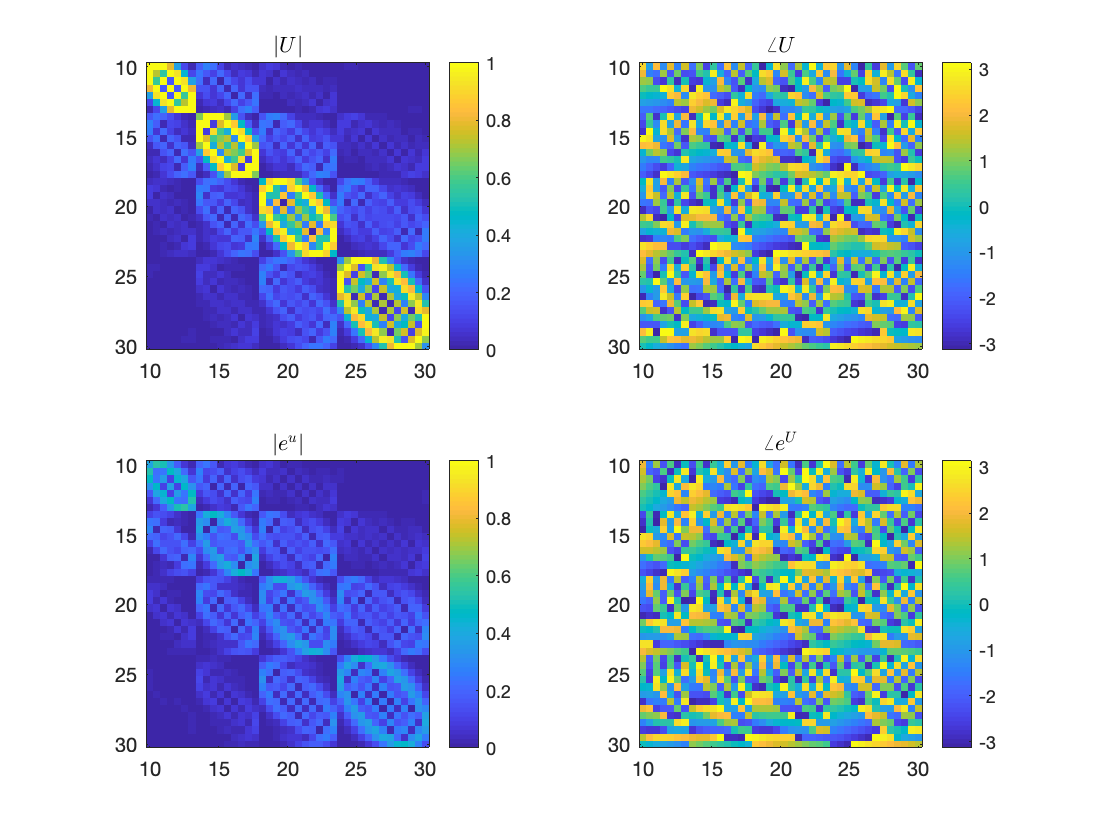

L = max(l1(end), l(end));
size = (L+1)^2-s^2;
h = figure; set(h, 'defaulttextinterpreter', 'latex');
mid_part = floor(size/4):1:ceil(size*3/4);
clims = [0 1];  % ignore terms with extreme values
subplot(2,2,1); imagesc(mid_part, mid_part, abs(U), clims); colorbar; title('$|U|$');
subplot(2,2,2); imagesc(mid_part, mid_part, angle(U)); colorbar; title('$\angle U$')
subplot(2,2,3); imagesc(mid_part, mid_part, abs(U_exp), clims); colorbar; title('$|e^u|$');
subplot(2,2,4); imagesc(mid_part, mid_part, angle(U_exp)); colorbar; title('$\angle e^U$');